# TD5 - Optimisation non-linéaire

clear 
close all
clc

## Paramétrisation

On commence par définir les paramètres de notre système (contenus dans Data_multi_gaussian.mat), ainsi que la solution initiale p0.

load('Data_multi_gaussian.mat')
N=length(ydata);
xdata=(1:N)';

p0=[1,50,1,1,100,1,1,180,1,0];

## Partie 1 : Premier essai avec lsqnonlin

Dans cette première partie, on fait un premier test de la fonction lsqnonlin sans options.

p = lsqnonlin(@(p) fun(p,xdata,ydata), p0);


Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the default value of the function tolerance.

<stopping criteria details>



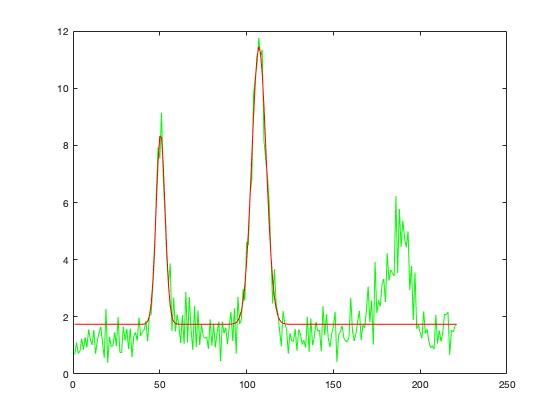

figure
plot(xdata,ydata,'g')
hold on
plot(xdata,fun(p,xdata,ydata)+ydata,'r')

On constate ici que la descente de gradient n'est donc pas suffisante pour résoudre notre système.

## Partie 2 : Levenberg-Marquardt

Suite à l'echec de la Partie 1, on exploite maintenant les propriétés des matrices jacobiennes grace à la méthode de Levenberg-Marquardt. Il suffit de changer les options de lsqnonlin.

options = optimoptions('lsqnonlin','Jacobian','on','Algorithm','levenberg-marquardt','Display','iter');
p = lsqnonlin(@(p) fun(p,xdata,ydata), p0, [], [], options);


                                        First-Order                    Norm of 
 Iteration  Func-count    Residual       optimality      Lambda           step
     0           1         2186.26             521         0.01
     1           2         892.711            61.1        0.001        8.98014
     2           5         863.136             129          0.1        22.8603
     3           6         524.006            33.8         0.01          14.36
     4           7         341.115            39.6        0.001        23.4263
     5           8         100.407            19.6       0.0001        6.20789
     6           9         75.5051            1.44        1e-05        1.35726
     7          10         74.8414           0.121        1e-06       0.438015
     8          11         74.8274          0.0504        1e-07       0.109476
     9          12         74.8257          0.0174        1e-08      0.0354406
    10          13         74.8254         0.00677        1e-09  

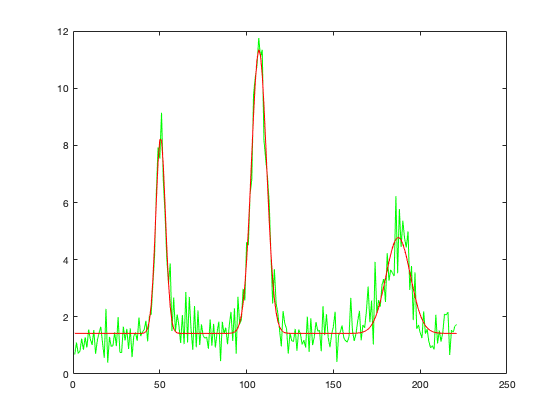

figure
plot(xdata,ydata,'g')
hold on
plot(xdata,fun(p,xdata,ydata)+ydata,'r')

Le résultat est alors bien meilleur, les trois gaussiennes sont détéctées.

## Partie 3 : Gauss-Newton

On applique maintenant la méthode de Gauss-Newton à notre problème afin de comprendre l'influence des matrices jacobiennes.

p=p0';
[y,J]=fun(p,xdata,ydata);

normeOpt=y'*y;

for i=1:200
    
    H=J'*J;
    
    if rcond(inv(H)) < 1e-10
        break
    end
    
    D=J'*y;
    p=p-0.2*(H\D);
    
    [y,J]=fun(p,xdata,ydata);
    
    norme=y'*y;
    
    if normeOpt-norme < 0.1
        break
    end
    
    if norme<normeOpt
        normeOpt=y'*y
        pOpt=p;
        iteration=i;
    end
    
end

normeOpt = 1.6752e+03

normeOpt = 1.3224e+03

normeOpt = 976.9506

normeOpt = 730.2797

normeOpt = 494.7572

normeOpt = 341.5687

normeOpt = 246.0964

normeOpt = 184.8248

normeOpt = 145.4616

normeOpt = 120.1841

normeOpt = 103.9565

normeOpt = 93.5399

normeOpt = 86.8532

normeOpt = 82.5601

normeOpt = 79.8031

normeOpt = 78.0318

normeOpt = 76.8933

normeOpt = 76.1609

normeOpt = 75.6895

normeOpt = 75.3856

normeOpt = 75.1896

normeOpt = 75.0628


normeOpt

normeOpt = 75.0628

pOpt

pOpt =     6.8436
   50.4652
    2.7616
    9.8041
  107.1407
    4.3264
    3.2771
  187.2594
    7.1150
    1.4118


iteration

iteration = 22

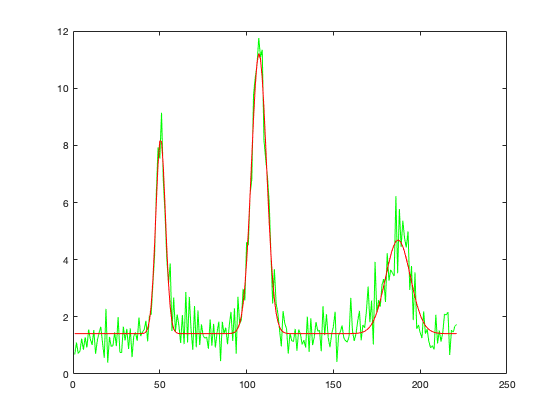

figure
plot(xdata,ydata,'g')
hold on
plot(xdata,fun(pOpt,xdata,ydata)+ydata,'r')

Cette méthode permet de résoudre le système, mais demande plus d'itérations que la précédente.